## **Problem 4**

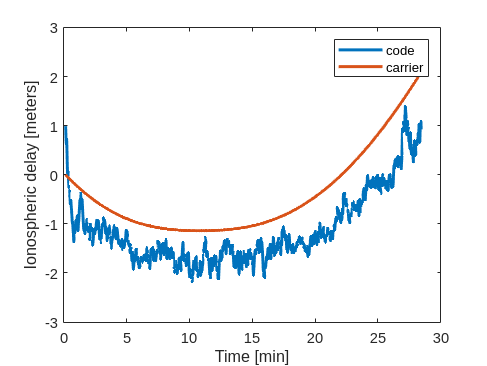

clc; close all; clear all;

% Load the data
load("gridDataUt6/channel.mat");
M = channel';

% Calculate the Ionopheric delay and plot it
TXID = 7;
[t, I_L1_code, I_L2_code, I_L1_carrier, I_L2_carrier] = ...
                                            dualFreqIonoDelay(M, TXID);
fig = plotIonoDelay(t, I_L1_code, 'code', NaN);
fig = plotIonoDelay(t, I_L1_carrier, 'carrier', fig);


% Interpret the "fast" variations
load("gridDataUt6/navsol.mat");
M = navsol';

lla = ecef2lla( M(:,4:6), 'WGS84' ); % plot(lla(:,3))

lla =           2.56580169582671           17.894173814727          108817.923067105
          2.63711467043603          17.8937715023068          108837.356680185
          2.70842701121178          17.8933695041188          108857.307008944
          2.77973875331806          17.8929676874041          108877.780168869
          2.85105006806255          17.8925663371226          108898.736600084
           2.9229312962587          17.8921622466244          108920.503151011
          2.99424150886033          17.8917619917897          108942.569249533
          3.06555108002127          17.8913621912094           108965.08325448
          3.13685981931722          17.8909628740264          108988.179729857
          3.20816820581047          17.8905638115624          109011.807397461


velocity =          -309.743303208949         -147.815456976372          8013.64801149991
         -318.715779211011         -150.675933386205           8013.1975881388
         -327.783082589102         -153.541812382945          8012.75041426094
          -336.78743766488         -156.366262194602          8012.29016284743
         -345.700414818286         -159.215540836649          8011.83074017575
          -354.71079408888         -162.076962506509          8011.34671465942
         -363.759533506331         -164.965563500792          8010.84551573852
         -372.736638904685         -167.782045298862          8010.35262198738
            -381.803636422         -170.653407112963          8009.85025729355
         -390.743570869725         -173.505948589911          8009.35457635109


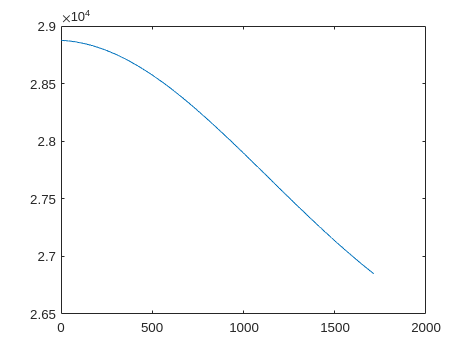

velocity = M(:,8:10);   % plot(vecnorm(velocity,2,2))

% Looks like this receiver was in LEO orbit.

## **Problem 5**

clc; close all; clear all;

ionodata.broadcast.alpha0 =  1.1176e-008;
ionodata.broadcast.alpha1 =  7.4506e-009;
ionodata.broadcast.alpha2 = -5.9605e-008;
ionodata.broadcast.alpha3 = -5.9605e-008;
ionodata.broadcast.beta0 = 90112;
ionodata.broadcast.beta1 = 0;
ionodata.broadcast.beta2 = -196610;
ionodata.broadcast.beta3 = -65536;
fc = 1575.42e6;
rRx = [ -742005.851560607; -5462223.38476596; 3198008.7346792  ];
rSv = [  20847329.7083373; -15185642.4780402; 6205281.68907901 ];
tGPS.week = 1575;
tGPS.seconds = 518201.501;

delTauG = getIonoDelay(ionodata, fc, rRx, rSv, tGPS, 'broadcast');
I = physconst('LightSpeed')*delTauG

I =           6.99323264131051


delTauG*1e9

ans =           23.3269131850892


## **Problem 6**

clc; close all; clear all;

ionodata.broadcast.alpha0 = 4.6566e-009;
ionodata.broadcast.alpha1 = 1.4901e-008;
ionodata.broadcast.alpha2 = -5.9605e-008;
ionodata.broadcast.alpha3 = -5.9605e-008;
ionodata.broadcast.beta0  = 79872;
ionodata.broadcast.beta1  = 65536;
ionodata.broadcast.beta2  = -65536;
ionodata.broadcast.beta3  = -393220;

tGPS.week = 1490;
tGPS.seconds = 146238.774036515;

rRx = [1101972.5309609; -4583489.78279095; 4282244.3010423];
rSV_txid29 = [24597807.6872883; -3065999.1384585; 9611346.77939927];
rSV_txid31 = [2339172.27088689; -16191391.3551878; 21104185.0481546];

% Load the data
load("gridDataUt1/channel.mat");
M = channel';

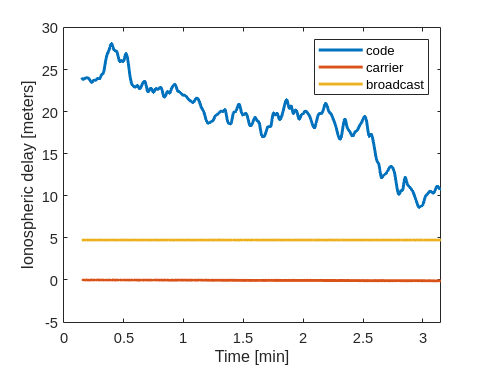

% Calculate the Ionopheric delay and plot it
TXID = 29;
[t_txid29, I_L1_code29, I_L2_code29, I_L1_carrier29, I_L2_carrier29] = ...
                                                        dualFreqIonoDelay(M, TXID);
fig_txid29 = plotIonoDelay(t_txid29, I_L1_code29, 'code', NaN);
fig_txid29 = plotIonoDelay(t_txid29, I_L1_carrier29, 'carrier', fig_txid29);

% Calculate the Ionopheric delay and plot it
TXID = 31;
[t_txid31, I_L1_code31, I_L2_code31, I_L1_carrier31, I_L2_carrier31] = ...
                                                        dualFreqIonoDelay(M, TXID);
fig_txid31 = plotIonoDelay(t_txid31, I_L1_code31, 'code', NaN);
fig_txid31 = plotIonoDelay(t_txid31, I_L1_carrier31, 'carrier', fig_txid31);

f_L1 = 1575.42 * 1e6;
[delTauG_txid29] = getIonoDelay(ionodata,f_L1,rRx,rSV_txid29,tGPS,'broadcast');
I_L1_broadcast29 = physconst('LightSpeed')*delTauG_txid29 * ones(size(t_txid29));
fig_txid29 = plotIonoDelay(t_txid29, I_L1_broadcast29, 'broadcast', fig_txid29);

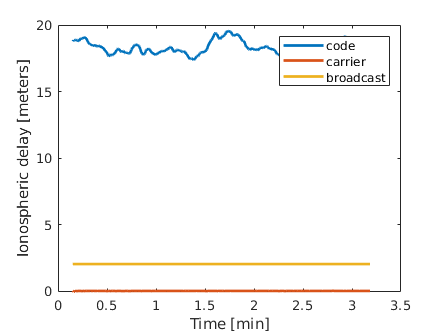


[delTauG_txid31] = getIonoDelay(ionodata,f_L1,rRx,rSV_txid31,tGPS,'broadcast');
I_L1_broadcast31 = physconst('LightSpeed')*delTauG_txid31 * ones(size(t_txid29));
fig_txid31 = plotIonoDelay(t_txid31, I_L1_broadcast31, 'broadcast', fig_txid31);

## **Problem 9**

clc; close all; clear all;

load("scintSim/scintDat.mat");
[S4, tau0] = computeS4AndTau0(zkhist, tkhist)

S4 = 0.8250

tau0 = 0.2200